load("pc_fmu2.mat");

disp(pc_fmu2(:,51))

   1.0e+03 *

    0.0050
    0.0017
    0.0005
    0.0003
    0.0003
    0.0004
    0.0000
    0.0712
    0.0011
    0.0016
    0.1035
    0.0001
    0.0007
    0.0002
         0
    0.0801
    0.0020
    0.0021
    2.7912
    0.0762
    0.3024
    0.0568
    0.0033
    0.0459
    0.0063
    0.0041
    0.0068
    0.0083
    0.0075
    0.0047
    0.0006
    0.0008
    0.0008
    0.0008
    0.0006
    0.0004
    0.0006
    0.0007
    0.0007
    0.0007




file_transient = "transient_output.xlsx";
writematrix(pc_fmu2, file_transient);

t2 = pc_fmu2(1,:);

anode_out_mf2 = pc_fmu2(4:7, :);
cathode_out_mf2 = pc_fmu2(12:15, :);
temperatures2 = pc_fmu2([8,16,20], :);
pressures2 = pc_fmu2([2,10,18], :);
voltages2 = pc_fmu2(21:24, :);
RH_anode2 = pc_fmu2(31:35, :);
RH_av_anode2 = sum(RH_anode2(:,:))/5;
RH_cathode2 = pc_fmu2(35:39, :);
RH_av_cathode2 = sum(RH_cathode2(:,:))/5;
membrane2 = pc_fmu2(25:30, :);

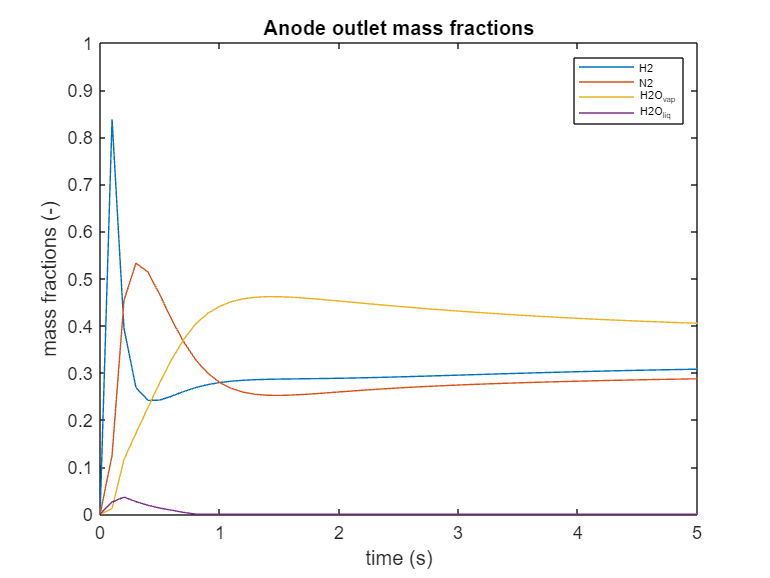

plot(t2, anode_out_mf2)
hold on
ylim([0, 1])
legend("H2" , "N2" , "H2O_vap" , "H2O_liq", 'Fontsize', 6)
xlabel("time (s)")
ylabel("mass fractions (-)")
title("Anode outlet mass fractions")
hold off

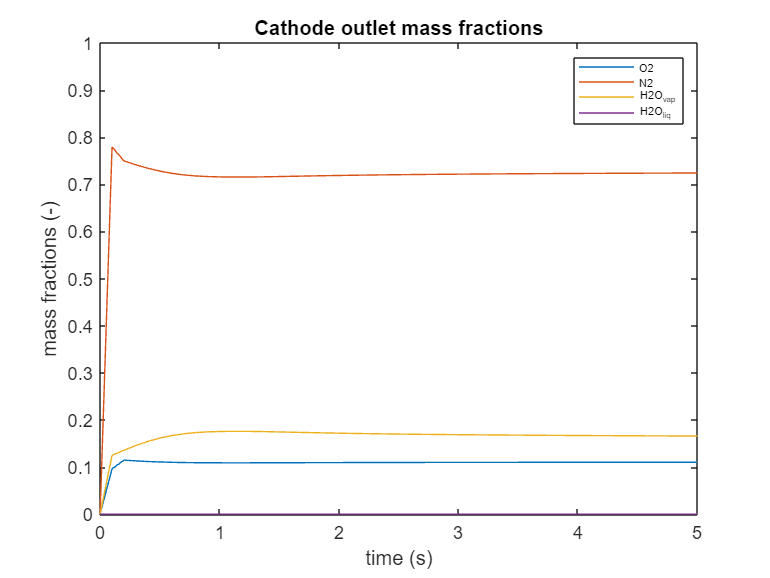



plot(t2, cathode_out_mf2)
hold on
ylim([0, 1])
legend("O2" , "N2" , "H2O_vap" , "H2O_liq", 'Fontsize', 6)
xlabel("time (s)")
ylabel("mass fractions (-)")
title("Cathode outlet mass fractions")
hold off

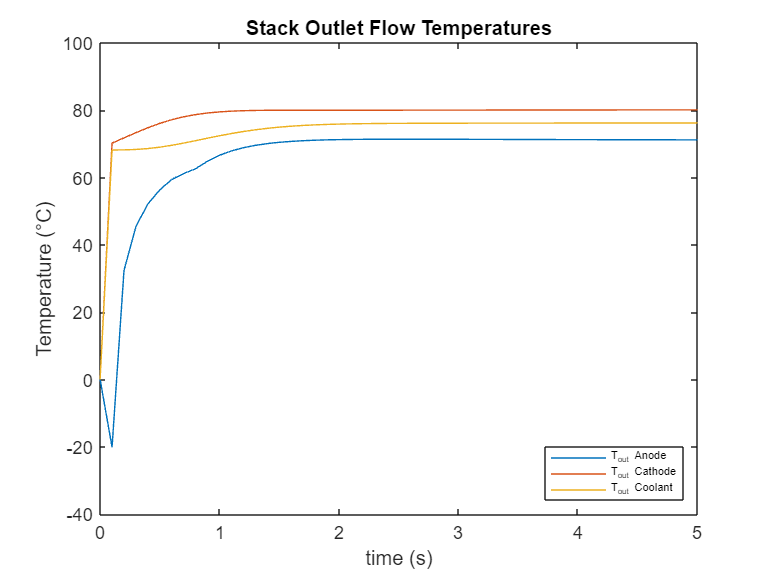



plot(t2, temperatures2)
hold on
ylim([-40, 100])
legend("T_out Anode" , "T_out Cathode" , "T_out Coolant" , "Location" , "southeast",'Fontsize', 6)
xlabel("time (s)")
ylabel("Temperature (°C)")
title("Stack Outlet Flow Temperatures")
hold off

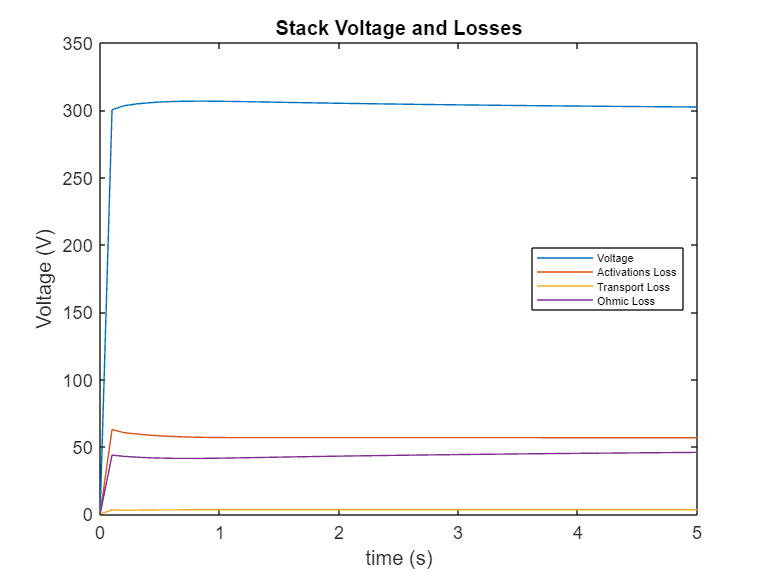



plot(t2, voltages2)
hold on
ylim([0, 350])
legend("Voltage" , "Activations Loss" , "Transport Loss" , "Ohmic Loss", "Location" , "east",'Fontsize', 6)
xlabel("time (s)")
ylabel("Voltage (V)")
title("Stack Voltage and Losses")
hold off

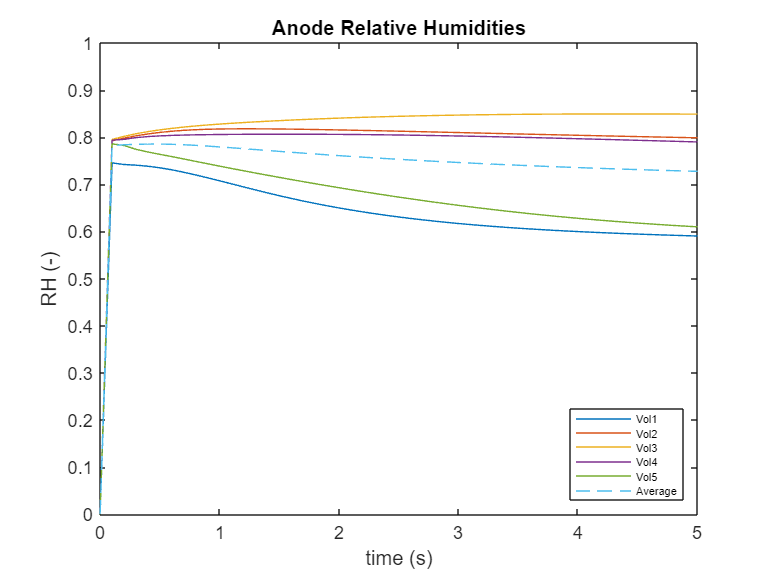



plot(t2, RH_anode2)
hold on
plot(t2, RH_av_anode2, "--")
ylim([0, 1])
legend("Vol1" , "Vol2" , "Vol3" , "Vol4","Vol5" , "Average" , "Location" , "southeast",  'Fontsize', 6)
xlabel("time (s)")
ylabel("RH (-)")
title("Anode Relative Humidities")
hold off

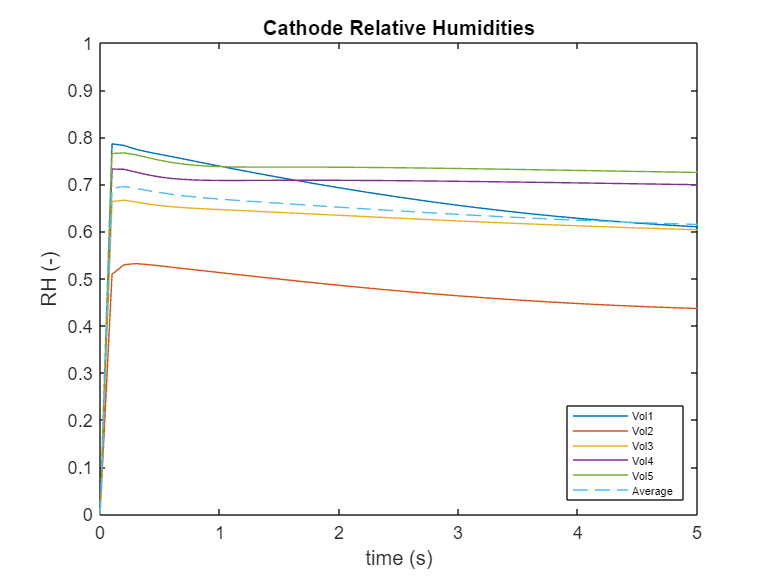


plot(t2, RH_cathode2)
hold on
plot(t2, RH_av_cathode2, "--")
ylim([0, 1])
legend("Vol1" , "Vol2" , "Vol3" , "Vol4","Vol5" , "Average" , "Location" , "southeast",  'Fontsize', 6)
xlabel("time (s)")
ylabel("RH (-)")
title("Cathode Relative Humidities")
hold off

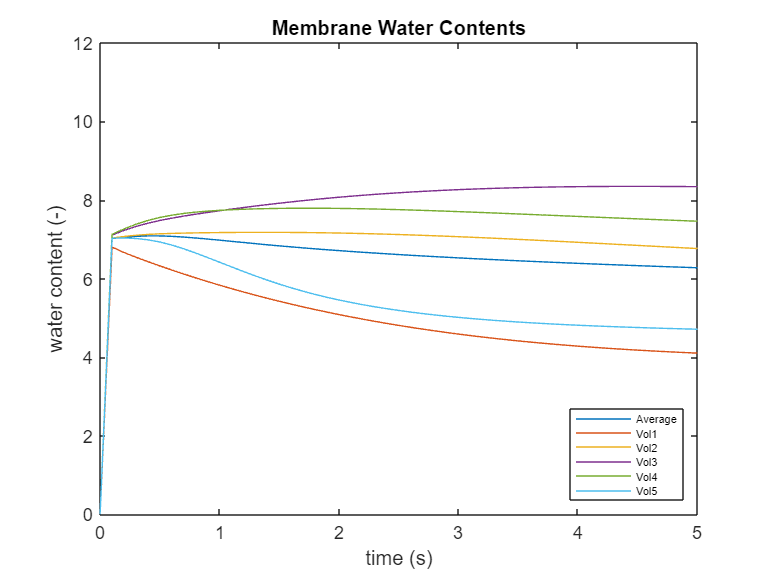



plot(t2, membrane2)
hold on
ylim([0, 12])
legend("Average", "Vol1" , "Vol2" , "Vol3" , "Vol4","Vol5" , "Location" , "southeast",  'Fontsize', 6)
xlabel("time (s)")
ylabel("water content (-)")
title("Membrane Water Contents")
hold off

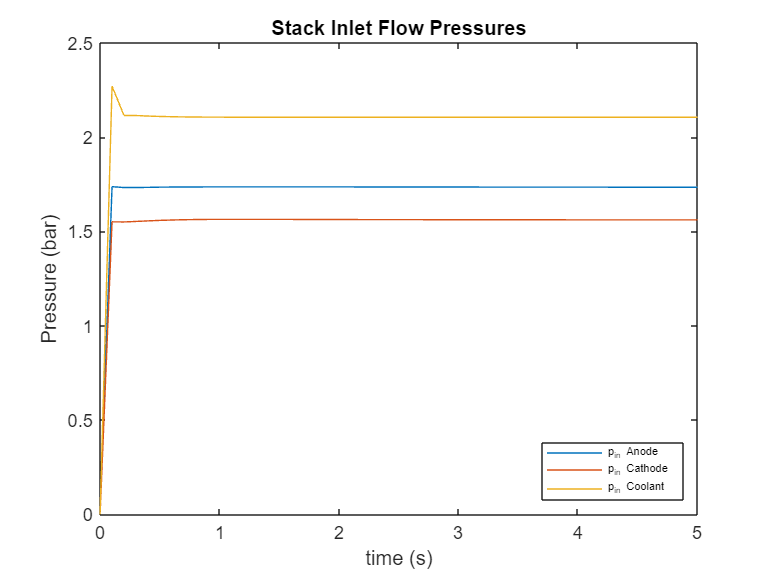


plot(t2, pressures2)
hold on
ylim([0, 2.5])
legend("p_in Anode" , "p_in Cathode" , "p_in Coolant" , "Location" , "southeast",'Fontsize', 6)
xlabel("time (s)")
ylabel("Pressure (bar)")
title("Stack Inlet Flow Pressures")
hold off